# ASYNCHRONOUS ACTIVITY

**DATE:**** 06-03-2021**

### GROUP MEMBERS

#### MANOJ KUMAR                2048015

#### R AKHILANDESHWARI    2048046

### **Colour image processing (Eg: changing the color of the leaf / Shirt/ Flower as per the user input)**

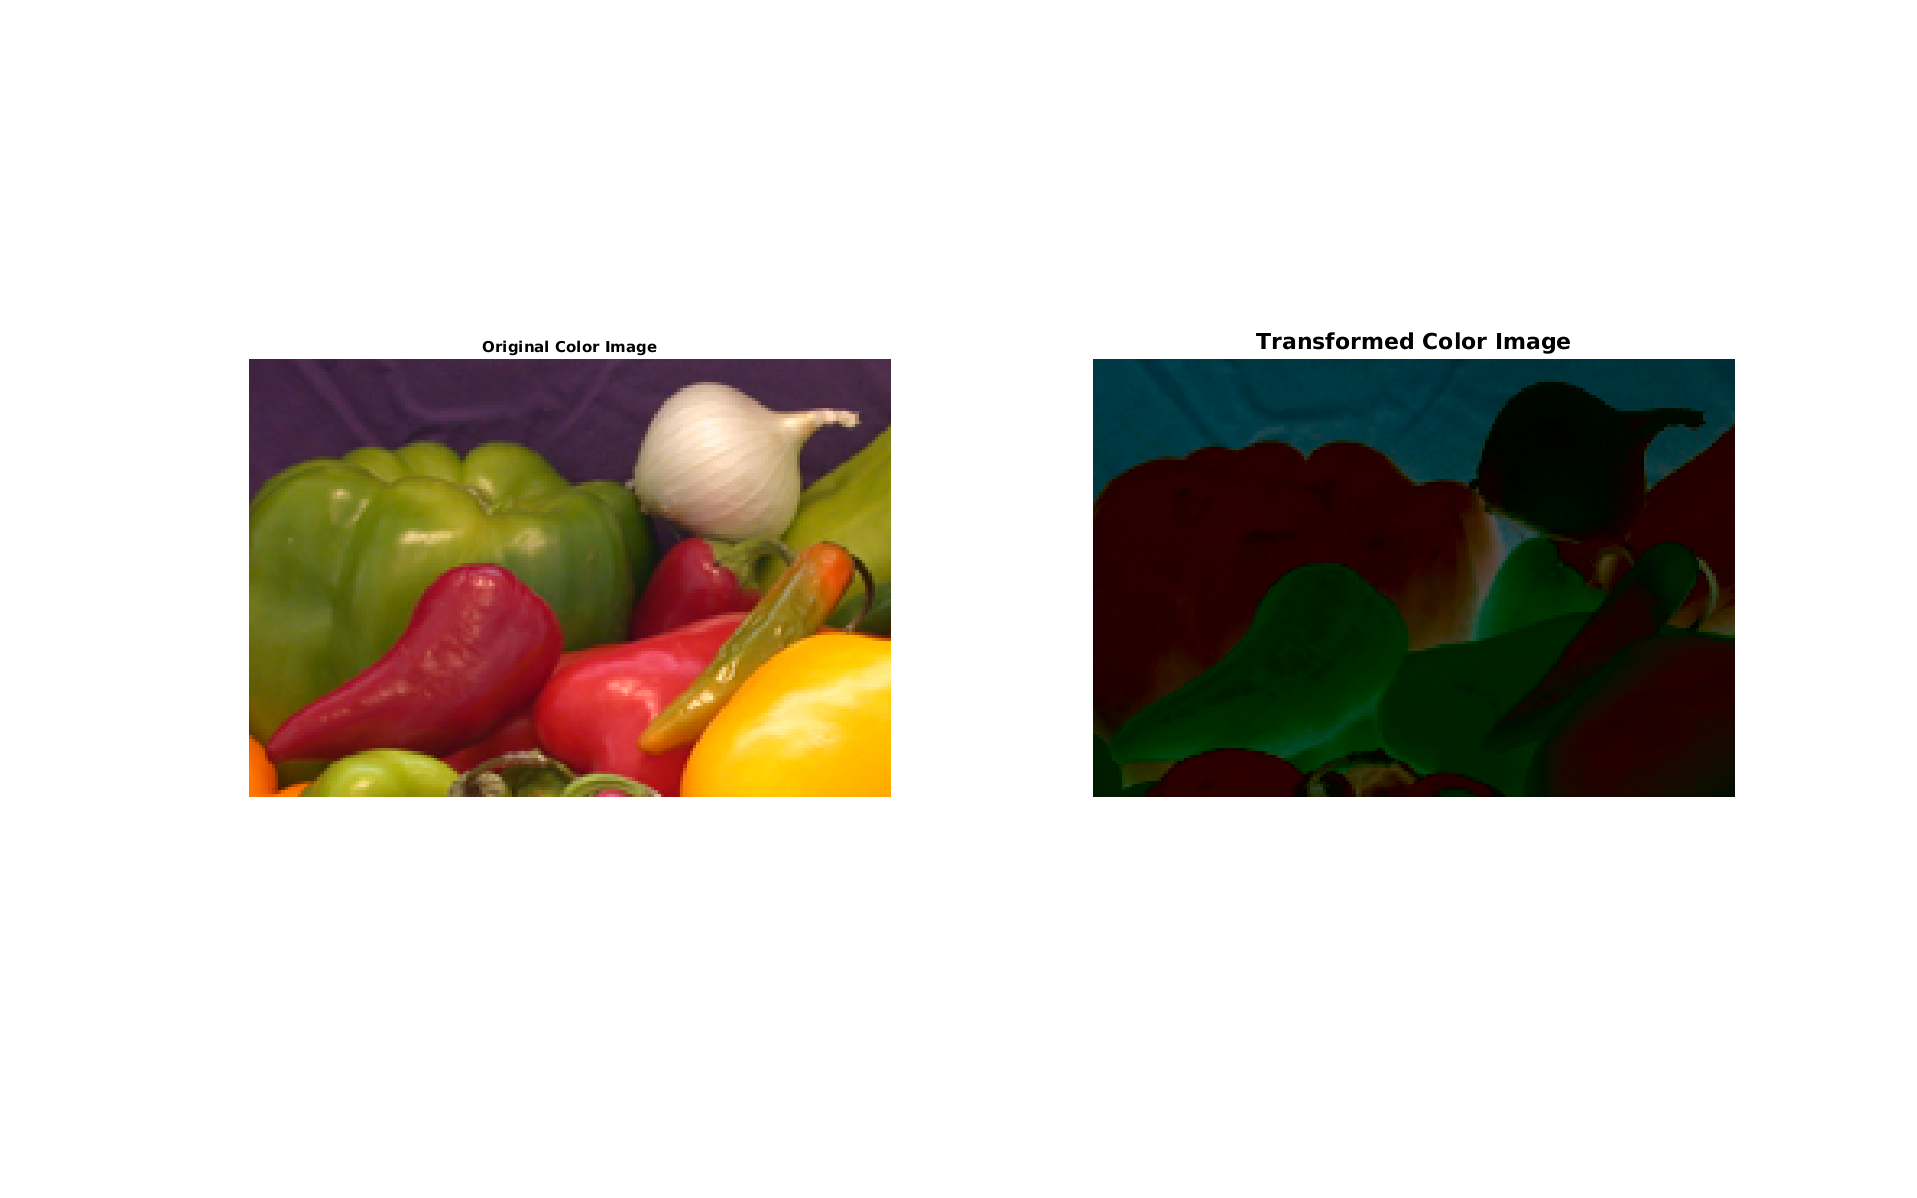

clc;
close all;
workspace;
clear;
fontSize = 16;
% Read in a standard MATLAB color demo image.
folder = fullfile(matlabroot, '\toolbox\images\imdemos');
baseFileName = 'onion.png';
fullFileName = fullfile(folder, baseFileName);
% Get the full filename, with path prepended.
fullFileName = fullfile(folder, baseFileName);
if ~exist(fullFileName, 'file')
  % Didn't find it there.  Check the search path for it.
  fullFileName = baseFileName; % No path this time.
  if ~exist(fullFileName, 'file')
    % Still didn't find it.  Alert user.
    errorMessage = sprintf('Error: %s does not exist.', fullFileName);
    uiwait(warndlg(errorMessage));
    return;
  end
end
rgbImage = imread(fullFileName);
% Get the dimensions of the image.  numberOfColorBands should be = 3.
[rows columns numberOfColorBands] = size(rgbImage);
% Display the original color image.
subplot(1, 2, 1);
imshow(rgbImage, []);
title('Original Color Image', 'FontSize', fontSize);
% Enlarge figure to full screen.
set(gcf, 'Position', get(0,'Screensize')); 
cform = makecform('srgb2lab');
lab = applycform(rgbImage, cform); 
L_channel = lab(:,:,1);
A_channel = lab(:,:,2);
B_channel = lab(:,:,3);
L_channelNew = 100 - L_channel;
A_channelNew = 255-A_channel;
labNew = cat(3, L_channelNew, A_channelNew, B_channel);
cform2 = makecform('lab2srgb');
rgbNew = applycform(labNew,cform2); 
% Display the new color image.
subplot(1, 2, 2);
imshow(rgbNew, []);
title('Transformed Color Image', 'FontSize', fontSize);

### **Sharpening of color image**

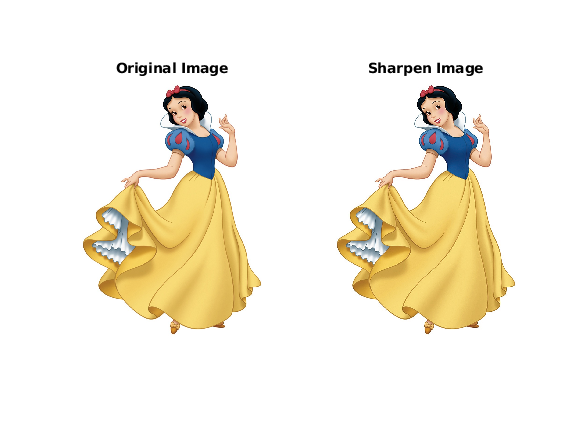

clc;
I = imread('SNOW_WHITE.jpg');
sharp = imsharpen(I);
figure
subplot(1,2,1);imshow(I); title('Original Image');
subplot(1,2,2);imshow(sharp); title('Sharpen Image');

### **Smoothening of color images**

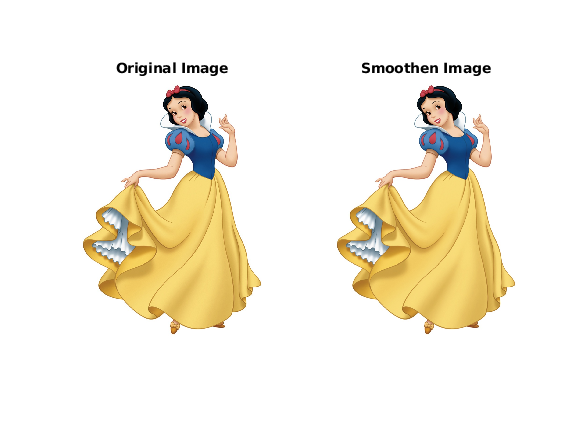

clc;
J = imread('SNOW_WHITE.jpg');
%Filter each channel separately
r = medfilt2(J(:, :, 1), [3 3]);
g = medfilt2(J(:, :, 2), [3 3]);
b = medfilt2(J(:, :, 3), [3 3]);
% reconstruct the image from r,g,b channels
K = cat(3,r,g,b);
figure
subplot(1,2,1);imshow(J); title('Original Image');
subplot(1,2,2);imshow(K); title('Smoothen Image');

### **Enhancement of color images using power law or contrast stretching (Any method)**

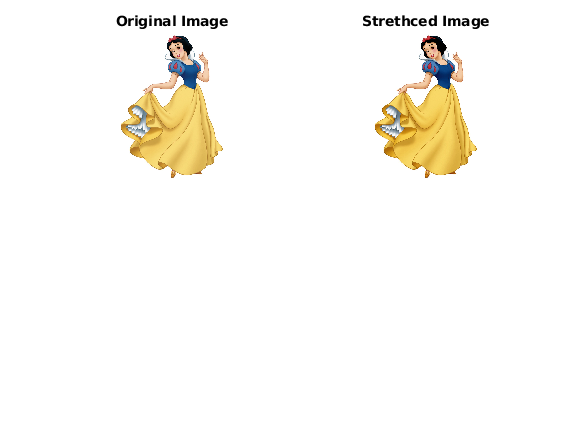

clc;
I = imread('SNOW_WHITE.jpg');
J = imadjust(I,stretchlim(I),[]);
% Subplot
figure
subplot(2,2,1), imshow(I), title('Original Image');
subplot(2,2,2), imshow(J), title('Strethced Image');

### **Separate High frequency and Low frequency of two different images and merge the images**

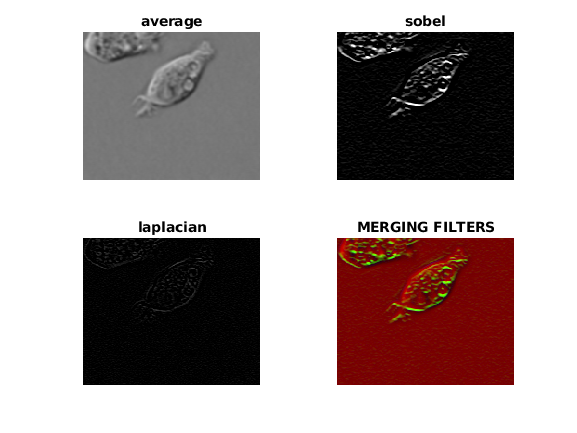

clf;
I = imread('cell.tif');
J1 = fspecial('average');
K1 = imfilter(I,J1,'replicate');
J2 = fspecial('sobel');
K2 = imfilter(I,J2,'replicate');
J3 = fspecial('laplacian');
K3 = imfilter(I,J3,'replicate');
subplot(221);imshow(K1);title('average');
subplot(222);imshow(K2);title('sobel');
subplot(223);imshow(K3);title('laplacian');
FIN= cat(3,K1,K2,K3);
subplot(224);imshow(FIN);title('MERGING FILTERS');

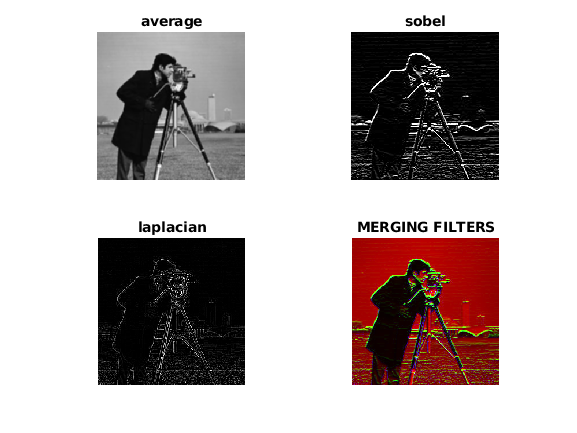

clf;
I = imread('cameraman.tif');
J1 = fspecial('average');
K1 = imfilter(I,J1,'replicate');
J2 = fspecial('sobel');
K2 = imfilter(I,J2,'replicate');
J3 = fspecial('laplacian');
K3 = imfilter(I,J3,'replicate');
subplot(221);imshow(K1);title('average');
subplot(222);imshow(K2);title('sobel');
subplot(223);imshow(K3);title('laplacian');
FIN= cat(3,K1,K2,K3);
subplot(224);imshow(FIN);title('MERGING FILTERS')

### **Applying Homomorphic filter to the Image / Audio**

clear all;
%read input image
dim=imread('onion.png');
cim=double(dim);
[r,c]=size(dim);
cim=cim+1;
% add 1 to pixels to remove 0 values which would result in undefined log values
% natural log
lim=log(cim);
%2D fft
fim=fft2(lim);
lowg=.9; %(lower gamma threshold, must be lowg < 1)
highg=1.1; %(higher gamma threshold, must be highg > 1)
% make sure the the values are symmetrically differenced
% function call
him=homomorph(fim,lowg,highg);
%inverse 2D fft
ifim=ifft2(him);
 
 
%exponent of result
eim=exp(ifim);
 
figure;
subplot(2,3,1);imshow(dim);title('Origional image');
subplot(2,3,2);imshow(lim);title('Natural Logarithm');
subplot(2,3,3);imshow(uint8(fim));title('Fourier transform');

subplot(2,3,4);imshow(him);title('Homomorphic filter');

subplot(2,3,5);imshow((ifim));title('Inverse fourier transform');

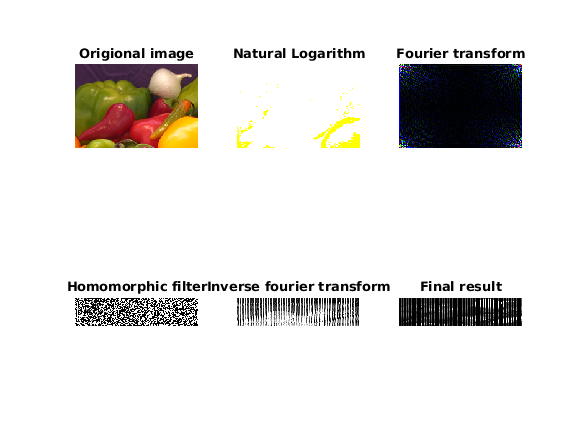

subplot(2,3,6);imshow(uint8(eim));title('Final result');

### **Image Flipping**

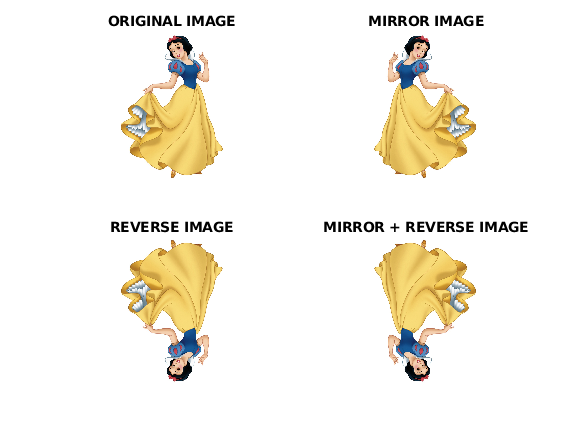

clc;
% Flipping Image
I_original = imread('SNOW_WHITE.jpg');
I_MIRROR = flipdim(I_original,2);
I_REVERSE = flipdim(I_original,1);
I_MIRRER = flipdim(I_REVERSE,2);

figure,
subplot(2,2,1),imshow(I_original);title('ORIGINAL IMAGE');
subplot(2,2,2),imshow(I_MIRROR);title('MIRROR IMAGE');
subplot(2,2,3),imshow(I_REVERSE);title('REVERSE IMAGE');
subplot(2,2,4),imshow(I_MIRRER);title('MIRROR + REVERSE IMAGE');

### **Implement bit plane slicing**

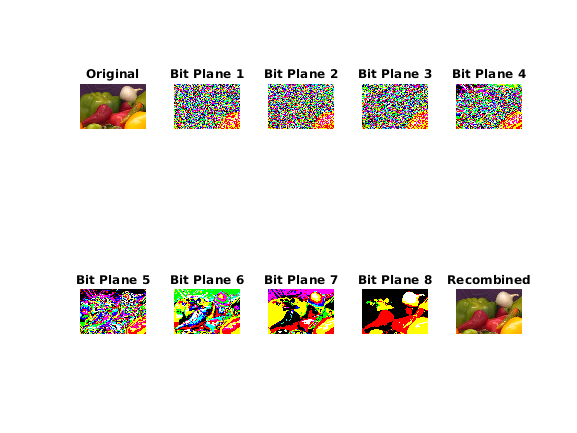

clf;
clear all;
% reading image's pixel in c
c = imread('onion.png');
% storing image information in cd
cd = double(c);

% extracting all bit one by one
% from 1st to 8th in variable
% from c1 to c8 respectively
c1 = mod(cd, 2);
c2 = mod(floor(cd/2), 2);
c3 = mod(floor(cd/4), 2);
c4 = mod(floor(cd/8), 2);
c5 = mod(floor(cd/16), 2);
c6 = mod(floor(cd/32), 2);
c7 = mod(floor(cd/64), 2);
c8 = mod(floor(cd/128), 2);

% combining image again to form equivalent to original grayscale image
cc = (2 * (2 * (2 * (2 * (2 * (2 * (2 * c8 + c7) + c6) + c5) + c4) + c3) + c2) + c1);

% plotting original image in first subplot
subplot(2, 5, 1);
imshow(c);
title('Original');

% plotting binary image having extracted bit from 1st to 8th 
% in subplot from 2nd to 9th
subplot(2, 5, 2); imshow(c1); title('Bit Plane 1');
subplot(2, 5, 3); imshow(c2); title('Bit Plane 2');
subplot(2, 5, 4); imshow(c3); title('Bit Plane 3');
subplot(2, 5, 5); imshow(c4); title('Bit Plane 4');
subplot(2, 5, 6); imshow(c5); title('Bit Plane 5');
subplot(2, 5, 7); imshow(c6); title('Bit Plane 6');
subplot(2, 5, 8); imshow(c7); title('Bit Plane 7');
subplot(2, 5, 9); imshow(c8); title('Bit Plane 8');

% plotting recombined image in 10th subplot
subplot(2, 5, 10);
imshow(uint8(cc));
title('Recombined');

function res = homomorph(im,lowg,highg)
% inputs
% im is the result of applying 2D fft on the input image
%lowg is the gammaLow value for homomorphic filtering
%highg is the gammaHigh value for homomorphic filtering
%outputs
% res is the homomorphic filtered image
dif=(highg-lowg); %(gammahigh-gammalow)
sig=15; %sigma of gaussian
[r,c]=size(im);
for i=1:r
    for j=1:c
   
    p=-(((i-(r/2))^2+(j-(c/2))^2)/(2*(sig^2)));
    k=(1/2*3.14*(sig^2));
    % term=(1-k*exp()) since this is a high pass gaussian filter
    % term=(k*exp()) for low pass gaussian filter
    term(i,j)=(1-k*exp(p) ); 
        
    end
end
for i=1:r
    for j=1:c
    h(i,j)=(dif*term(i,j))+lowg;
    end
end
for i=1:r
    for j=1:c
    res(i,j)=im(i,j)*h(i,j);
    end
end
end